close all;clear variables;

# Testbench for Hybrid coupler filter ABCD-parameter calculations

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 4e5; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency

### Filter-bank properties

Qi          = Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0;
S           = 1; % Oversampling


nFilters    = 1;
f0          = 440e9;

% TL-Impedance Assume a single impedance, simpler case
Z0  = 79.04;
Z0_KID      = 54.81;
Z0_skyline  = 79.04;

singleFilterPlot = nFilters; 

### Constants

mu0   = pi*4e-7;             % []    Permeability of FS
eps0  = 8.854187817620e-12;  % []    Permittivity of FS
c0    = 1/sqrt(eps0*mu0);  % [m/s] Speed of light in FS

### Through-line

Z0_thru      = Z0_skyline;
eps_eff_thru = 49.93;

lam_thru     = c0 ./ sqrt(eps_eff_thru) ./ f;
lam0_thru    = c0 ./ sqrt(eps_eff_thru) ./ f0;
l_thru       = sep*lam0_thru;
if ThruLineLosses
    kc_thru      = 2 .* pi ./ lam_thru * ( 1 - 1i ./ (2 .* Qi) ); %#ok<*UNRCH>
else
    kc_thru      = 2 .* pi ./ lam_thru;
end

### Resonator

Z0_res      = 54.81;
eps_eff_res = 47.28;

lam_res     = c0 ./ sqrt(eps_eff_res) ./ f;
lam0_res    = c0 ./ sqrt(eps_eff_res) ./ f0;
kc_res      = 2 .* pi ./ lam_res * ( 1 - 1i ./ (2 .* Qi) );

### Coupler C for given Ql

% Hack to get realized single filter Ql to 100.
CompensationFactor = 1.20;
C_coup_thru = findCcoupler_Ql('SERIES','L2',Ql_target.*CompensationFactor,Qi,f0,Z0_thru./2,Z0_res);
C_coup_KID  = findCcoupler_Ql('SERIES','L2',Ql_target.*CompensationFactor,Qi,f0,Z0_res,Z0_KID./2);

### Resonator lengths

lres_KID    = findResLength(f0,lam0_res,Z0_thru./2,Z0_KID./2,Z0_res,C_coup_thru,C_coup_KID);

## Filter-bank calculations

%%%% Parameters of each filter %%%%
Z_coup_KID            = -1i./(2 .* pi .* f .* C_coup_KID);
Z_coup_thru           = -1i./(2 .* pi .* f .* C_coup_thru);
L_res_KID             = lres_KID;
L_lambda4             = l_thru;
L_lambda8             = 0.5 .* L_lambda4;
L_3lambda4            = 3 .* l_thru;
L_3lambda8            = 0.5 .* L_3lambda4;

%%%% Elementary ABCD matrices %%%%
ABCD_Lambda8 = trxLine_ABCD(Z0_thru,1i.*kc_thru,L_lambda8);
ABCD_3Lambda8 = trxLine_ABCD(Z0_thru,1i.*kc_thru,L_3lambda8);
ABCD_Filter = filterBranch_ABCD(Z_coup_KID,Z0_res,1i.*kc_res,L_res_KID,Z_coup_thru);
% ABCD_ShuntLambda8OpenOld = shuntLoad_ABCD(Zin_fromABCD(ABCD_Lambda8,Inf));
% ABCD_ShuntLambda8ShortOld = shuntLoad_ABCD(Zin_fromABCD(ABCD_Lambda8,0));

Z_Lambda8Open = -1i .* Z0_thru .* cot(real(kc_thru).*L_lambda8);
Z_Lambda8Short = 1i .* Z0_thru .* tan(real(kc_thru).*L_lambda8);
ABCD_ShuntLambda8Open = shuntLoad_ABCD(Z_Lambda8Open);
ABCD_ShuntLambda8Short = shuntLoad_ABCD(Z_Lambda8Short);

Z_3Lambda8Open = -1i .* Z0_thru .* cot(real(kc_thru).*L_3lambda8);
Z_3Lambda8Short = 1i .* Z0_thru .* tan(real(kc_thru).*L_3lambda8);
ABCD_Shunt3Lambda8Open = shuntLoad_ABCD(Z_3Lambda8Open);
ABCD_Shunt3Lambda8Short = shuntLoad_ABCD(Z_3Lambda8Short);


%%%% Even mode ABCD %%%%
ABCD_1 = mmat(ABCD_ShuntLambda8Open,ABCD_Filter,[1,2]);
ABCD_even = mmat(ABCD_1,ABCD_Shunt3Lambda8Open,[1,2]);

%%%% Odd mode ABCD %%%%
ABCD_1 = mmat(ABCD_ShuntLambda8Short,ABCD_Filter,[1,2]);
ABCD_odd = mmat(ABCD_1,ABCD_Shunt3Lambda8Short,[1,2]);


S_even = a2s(ABCD_even,[Z0_thru,Z0_KID]);
G_even = squeeze(S_even(1,1,:));
T_even = squeeze(S_even(2,1,:));

S_odd = a2s(ABCD_odd,[Z0_thru,Z0_KID]);
G_odd = squeeze(S_odd(1,1,:));
T_odd = squeeze(S_odd(2,1,:));

S_11 = 0.5 .* G_even + 0.5 .* G_odd;
S_21 = 0.5 .* T_even + 0.5 .* T_odd;
S_31 = 0.5 .* T_even - 0.5 .* T_odd;
S_41 = 0.5 .* G_even - 0.5 .* G_odd;


% Q realized
fq = linspace(f(1),f(end),nF*50);
S_21_q = interp1(f,S_21,fq);

[~,i_f0_actual] = findpeaks(abs(S_21_q).^2,'WidthReference','HalfHeight','MinPeakProminence',0.5*max(abs(S_21_q).^2),'NPeaks',1,'Annotate','extents');

if fq(i_f0_actual) < max(f)/2
    inband = abs(S_21_q(1:2*i_f0_actual)).^2 >= 0.5.*max(abs(S_21_q(1:2*i_f0_actual)).^2);
else
    inband = abs(S_21_q).^2 >= 0.5.*max(abs(S_21_q).^2);
end

fprintf('Q = %d\n',round( f0 / (max(fq(inband)) - min(fq(inband))) ));

Q = 100


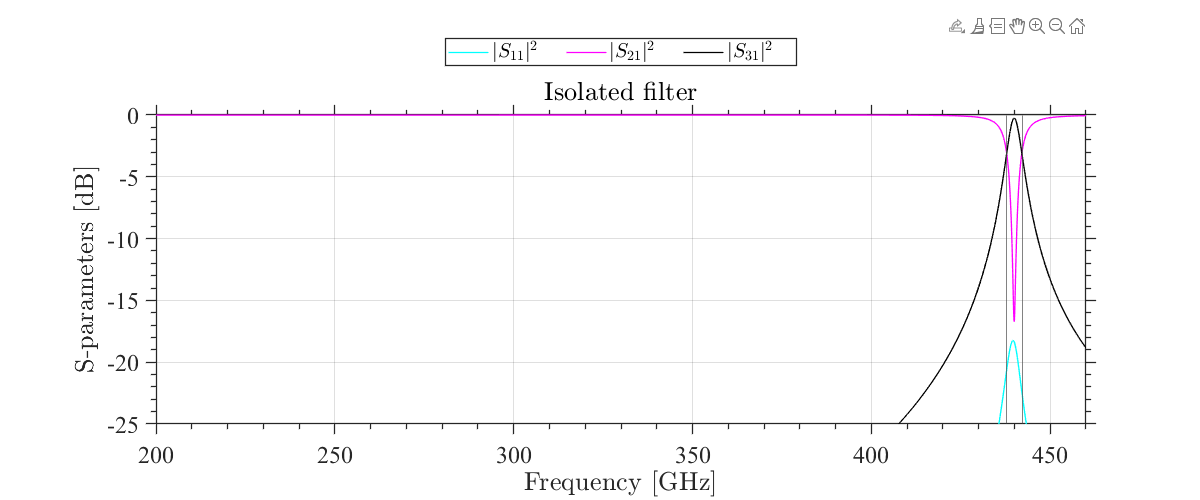



fig=figure();
fig.Position = [100 100 1200 500];
hold on;
set(gcf,'Visible','on');
hLegend(1) = niceplot(f/1e9,10*log10(abs(S_11).^2),'Color',[0 1 1],'LineWidth',1,'DisplayName','$|S_{11}|^2\quad$');
hLegend(2) = niceplot(f/1e9,10*log10(abs(S_41).^2),'Color',[1 0 1],'LineWidth',1,'DisplayName','$|S_{11}|^2\quad$');
hLegend(3) = niceplot(f/1e9,10*log10(abs(S_21).^2),'Color',[0 0 0],'LineWidth',1,'DisplayName','$|S_{11}|^2\quad$');
% hLegend(4) = niceplot(f/1e9,10*log10(abs(S_41).^2),'Color',[0.5 0.5 0.5],'LineWidth',1);

xline(min(fq(inband))/1e9,'Color',[0.3 0.3 0.3]);
xline(max(fq(inband))/1e9,'Color',[0.3 0.3 0.3]);

lgnd = {'$|S_{11}|^2\quad$','$|S_{21}|^2\quad$','$|S_{31}|^2\quad$'};
legend(hLegend,lgnd,'Interpreter','LaTeX','Location','NorthOutside','Orientation','Horizontal');
xlim([min(f),max(f)]/1e9);
ylim([-25,0]);
xlabel('Frequency [GHz]','Interpreter','LaTeX');
ylabel('S-parameters [dB]','Interpreter','LaTeX');
title('Isolated filter','Interpreter','LaTeX')

set(gca,"FontSize",18)
lh = findall(0,'Type','Legend');
set( findall(lh, '-property', 'fontsize'), 'fontsize', 15)